# Angiogensis Stochastic Modeling

In this document we are going to present the model of angiogensis based on fractional stochastic differential equations.

For this document we are going to document step by step the definitions of the different parameters that construct this model.

## Parameter Definition

For this model we star by defining the state of the random algorithm in order to be repeateble

% by defining this function we are 
% setting a initial seed for the semi-random
% algorithm, this is going to help us 
% to repeat the script and have the same
% results
randn('state',20)

After running this function we start by defining the paremeters that are going to make this model.

First we define the parameters that are going to define the Brownian Path

T = 1 % time from 0 to 1

T = 1

N = 500 % there are going to be 500 steps

N = 500

dt = T/N % the discrete steps of the brownian

dt = 0.0020

         % path

Now we are going to define the parameters for the Stochastic Differential Equation that is going to define the model.

This model is based in the equation that Stokes & Lauffenburger (1991) developed. This SDE is


$$d\vec{v_i \left(t\right)} =-\beta \;\vec{\;v_i \left(t\right)} \textrm{dt}+\sqrt{\;\alpha }\;\vec{\;{\textrm{dW}}_i \left(t\right)} +\kappa \vec{\;\bigtriangledown a} \;\sin \;\left|\frac{\;\phi_i }{2}\right|\;\textrm{dt}$$


$\beta \;$: decay rate constant of the current velocity

$\alpha :\;$represents the magnitude of random fluctuations and their effect on cell movement

$\kappa :$ the chemotactic responsiveness

$\vec{\bigtriangledown a} :$ attractant concentration gradient

$\phi :$ angle between the direction the tip is moving and that towards the attractant source

$\vec{\;v_i } :$ velocity of the tip of the sprout

$\vec{\;W_i } :$ Brownian path of mean 0 and variance $\alpha \;$

% based on the empirical data extracted
% from stokes and lauffenburger
beta = 1/3 % h^-1

beta = 0.3333

alpha = 40 * 1/3 %µm^2 h-3

alpha = 13.3333

% we define this parameter arbitrarialy
kappa = 10 

kappa = 10

## Brownian Path

Now we define the brownian path following the next equation


$$\begin{array}{l}
W_j =W_{j-1} +{\textrm{dW}}_j ,j=2,\ldotp \ldotp \ldotp ,N\\
W_1 =0\\
\textrm{dW}=\sqrt{\delta \;t}N\left(0,\alpha \right)
\end{array}$$


% we define the dW following the equation

dW =     0.0628   -0.0498   -0.0365   -0.0807   -0.0519    0.0077    0.0448    0.0710   -0.0947   -0.1462    0.0726   -0.0018    0.0427   -0.0743    0.0014    0.0035   -0.0041    0.0117    0.0830   -0.0216   -0.0235   -0.0065    0.0218    0.0188   -0.0330    0.0156    0.0147    0.0364   -0.0074   -0.0305    0.0617    0.0277   -0.0760    0.0233   -0.0306    0.0327    0.0171   -0.0524   -0.0577    0.0069   -0.0753   -0.0146    0.0228   -0.0659    0.0466    0.0208   -0.0033    0.0481    0.0175   -0.0381
    0.0527    0.0111   -0.0567   -0.0314   -0.0357   -0.0198   -0.0477   -0.0338    0.0302    0.0095    0.0237   -0.0284    0.0971    0.0886    0.0372    0.0417    0.0143   -0.0500   -0.0202    0.0744   -0.0122    0.0062    0.0357    0.0267   -0.0230   -0.0758   -0.0524   -0.0324    0.0010    0.0140    0.0407    0.0740    0.0011   -0.0264    0.0743   -0.0468   -0.0818   -0.0000    0.0111   -0.0204   -0.0175   -0.0107    0.0487   -0.0492   -0.0533   -0.0345   -0.0413   -0.0537    0.0177    

W =     0.0628   -0.0498   -0.0365   -0.0807   -0.0519    0.0077    0.0448    0.0710   -0.0947   -0.1462    0.0726   -0.0018    0.0427   -0.0743    0.0014    0.0035   -0.0041    0.0117    0.0830   -0.0216   -0.0235   -0.0065    0.0218    0.0188   -0.0330    0.0156    0.0147    0.0364   -0.0074   -0.0305    0.0617    0.0277   -0.0760    0.0233   -0.0306    0.0327    0.0171   -0.0524   -0.0577    0.0069   -0.0753   -0.0146    0.0228   -0.0659    0.0466    0.0208   -0.0033    0.0481    0.0175   -0.0381
    0.1155   -0.0388   -0.0932   -0.1121   -0.0877   -0.0122   -0.0029    0.0372   -0.0645   -0.1367    0.0963   -0.0302    0.1398    0.0143    0.0385    0.0453    0.0102   -0.0383    0.0628    0.0528   -0.0356   -0.0003    0.0575    0.0454   -0.0560   -0.0602   -0.0377    0.0040   -0.0064   -0.0165    0.1024    0.1017   -0.0749   -0.0031    0.0437   -0.0141   -0.0647   -0.0525   -0.0465   -0.0135   -0.0928   -0.0253    0.0714   -0.1151   -0.0066   -0.0137   -0.0446   -0.0056    0.0352   -0

% we definen 2 rows that contain N
% elements
% each row correspond with a spatial variable
dW = sqrt(dt)*randn(2,N)
% Now we define the brownian path by the 
% comulative sum of dW 
W = cumsum(dW)

Now we plot the brownian walk for the x variable and the y variable to see if it make sense

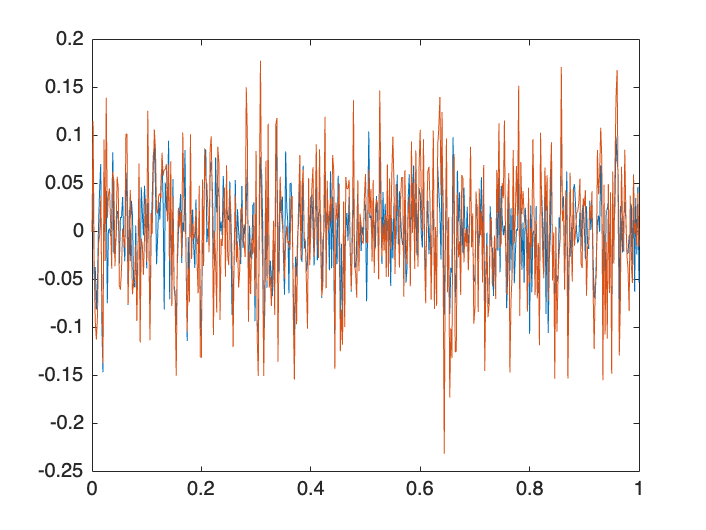

plot([0:dt:T],[0,W(1,:)]), hold on
plot([0:dt:T],[0,W(2,:)]), hold off

## Begining of the modeling

To solve the stochastic differential equation model we define the following L interger and stepsize $\Delta \;t=R\delta \;t$

R = 4;
Dt = R*dt;
L = N/R;

We initialize the solution vector

Xem = zeros(2,L); % first x
                  % second y
Vem = zeros(2,L);


Initialize the first point

Xzero = [0;0];
Xtemp = Xzero;
Vzero = [0;0];
Vtemp = Vzero;

And we initialize the first angles

theta = pi/2;
phi = pi/2;

We define the algorithm to calculate the $\vec{\;\Delta \;a}$

We define the gradient of attractant as


$$a=\frac{\;L}{1+b*\exp \left(-c*y\right)}$$



$$\Delta \;a=\left(0,\frac{\;L*b*c\;*\exp \left(-c*y\right)}{\left(1+b*{\left.\exp \left(-\textrm{cy}\right)\right)}^2 \right.}\right)$$


These equations have been implemented in the functions that are in the folder functions

addpath("angiogenesis_model/functions/")

The paremeters for the equation for the attractant are

a = 5;
b = 10^5;
c = 0.2;
da = []


da =

     []



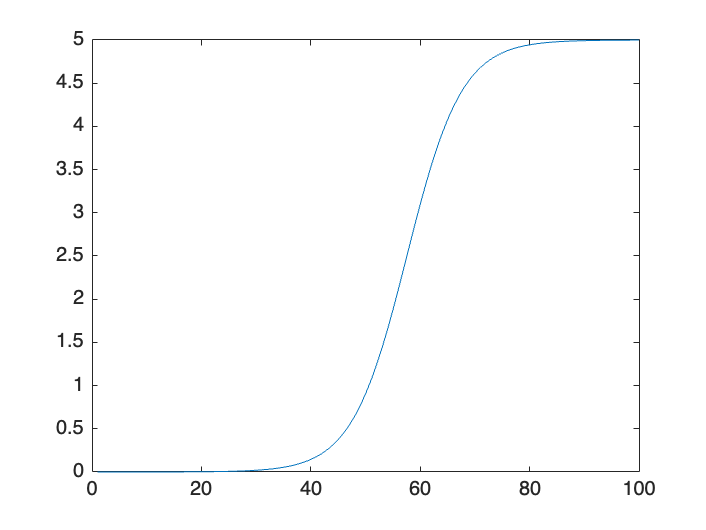

for i = 1:100
    da(i) = logistic_decay(a,b,c,i);
end
plot([1:100],da(:))

We beging the for loop for the model

for j = 1:L
    winc = sum(dW(:,R*(j-1)+1:R*j),2);
    DA = 2/10;
    Vtemp = Vtemp + (-beta * Vtemp + kappa * DA + sin(abs(phi/2)))*Dt + sqrt(alpha)*winc;
    Vem(:,j) = Vtemp;
    Xtemp = Xtemp + Vtemp * Dt;
    Xem(:,j) = Xtemp;
    if j ~= 1
        xj = Xem(1,j);
        yj = Xem(2,j);
        xj_1 = Xem(1,j-1);
        yj_1 = Xem(2,j-1);
        theta = atan((yj-yj_1)/(xj-xj_1));
        phi = calculate_phi( xj, yj , xj, 3, theta);
    end 
end

We see the array of solutions for the position

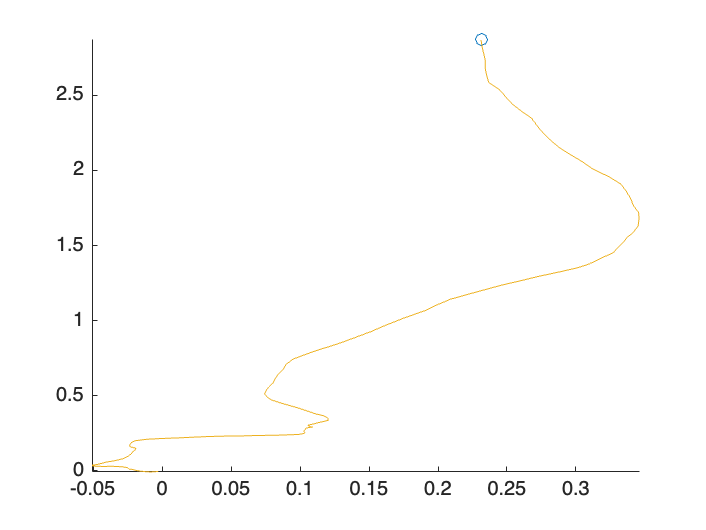

comet(Xem(1,:),Xem(2,:))